% Load YALMIP
addpath(genpath('C:\Users\Lu34\OneDrive\Desktop\Year 4 Project II\Matlab simulation\acn_data\final codes\YALMIP-master')); % Add path
yalmip('clear')
load profiles.mat
% 
% Make sure to replace 'path_to_python' with the actual path to your Python executable
% pyversion('C:\Users\Lu34\AppData\Local\Programs\Python\Python310\python.exe');

% Specify the path to the CSV file
csvFilePath = 'C:\Users\Lu34\OneDrive\Desktop\Year 4 Project II\Matlab simulation\acn_data\final codes\combined_hourly_csv.csv';

opts = detectImportOptions(csvFilePath);
opts.VariableNamingRule = 'preserve';

% Read the CSV file into a table in MATLAB
dataTable = readtable(csvFilePath, opts);

% Display the table
disp(dataTable);

           Hour            Location1_kWh         Location2_kWh              Location3_kWh         Total_kWh
    ___________________    _____________    _______________________    _______________________    _________

                    NaT           NaN       {'kWhDeliveredPerHour'}    {'kWhDeliveredPerHour'}         NaN 
    2018-04-25 11:00:00         2.644       {0×0 char             }    {0×0 char             }       2.644 
    2018-04-25 12:00:00         2.644       {0×0 char             }    {0×0 char             }       2.644 
    2018-04-25 13:00:00        1.3188       {0×0 char             }    {0×0 char             }      1.3188 
    2018-04-25 14:00:00        1.2953       {0×0 char             }    {0×0 char             }      1.2953 
    2018-04-25 15:00:00       0.76793       {0×0 char             }    {0

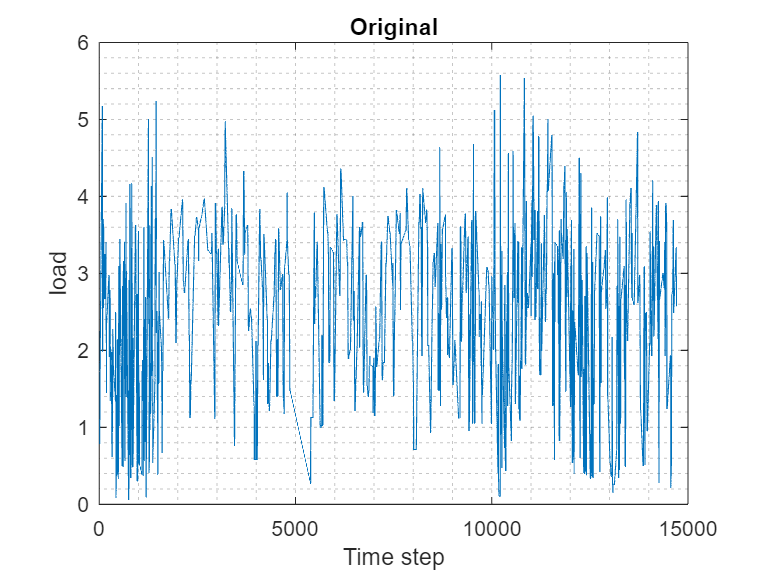


% Extract the second column
data = dataTable.Total_kWh(15000:end); 

% Interpolate NaN values using linear interpolation
data = fillmissing(data, 'linear');


% data = load;

% Continue with the rest of your MATLAB script using the loaded 'data'
figure;
plot(data);
xlabel("Time step");
ylabel("load");
title("Original");
grid minor;



% Split the data into training, validation, and test sets
numObservations = numel(data);
numTimeStepsTrain = floor(0.8*numel(data)); % Adjust the split ratio as needed
numTimeStepsValidation = floor(0.1*numel(data));

idxTrain = 1:numTimeStepsTrain;
idxValidation = numTimeStepsTrain+1:numTimeStepsTrain+numTimeStepsValidation;
idxTest = numTimeStepsTrain+numTimeStepsValidation+1:numObservations;

dataTrain = data(idxTrain);
dataValidation = data(idxValidation);
dataTest = data(idxTest);

% Standardize the data
mu = mean(dataTrain);
sig = std(dataTrain);
mu_1 = mean(dataValidation);
sig_1 = std(dataValidation);
mu_2 = mean(dataTest);
sig_2 = std(dataTest);
mu_3 = mean(data);
sig_3 = std(data);

dataTrainStandardized = (dataTrain - mu) / sig;
dataValidationStandardized = (dataValidation - mu_1) / sig_1;
dataTestStandardized = (dataTest - mu_2) / sig_2;


% Define parameters
P = 32; % Number of past values to consider
F = 6; % Number of future values to predict

% Prepare input-output pairs for training, validation, and test sets
XTrain = [];
YTrain = [];
XValidation = [];
YValidation = [];
XTest = [];
YTest = [];

% Generate training sets
for k = P+1:length(dataTrainStandardized)-F
    XTrain(k-P,:) = dataTrainStandardized(k-P:k-1);
    YTrain(k-P,:) = dataTrainStandardized(k:k+F-1);
end

% Generate validation sets
for k = P+1:length(dataValidationStandardized)-F
    XValidation(k-P,:) = dataValidationStandardized(k-P:k-1);
    YValidation(k-P,:) = dataValidationStandardized(k:k+F-1);
end

% Generate test sets
for k = P+1:length(dataTestStandardized)-F
    XTest(k-P,:) = dataTestStandardized(k-P:k-1);
    YTest(k-P,:) = dataTestStandardized(k:k+F-1);
end

% Reshape
XTrain = XTrain';
YTrain = YTrain';
XValidation = XValidation';
YValidation = YValidation';
XTest = XTest';
YTest = YTest';

display(XTrain)

XTrain =    -1.7330   -1.7330   -1.7330   -1.7330   -1.7330   -1.7330   -1.7330   -1.7330   -1.7330   -1.7330   -1.7330   -1.7330   -1.4281   -1.4281   -1.4281   -1.4281   -1.4281   -1.4281   -1.4198   -1.4198   -0.8183   -0.8183   -0.7592   -0.7001   -0.6410   -0.5819   -0.5228   -0.4636   -0.4045   -0.3454   -0.2863   -0.2272   -0.1681   -0.1089   -0.0498    0.0093    0.0684    0.1275    0.1866    0.2457    0.3049    0.3640    0.4231    0.4822    0.5413    0.6004    0.6595    0.7187    0.7778    0.8369
   -1.7330   -1.7330   -1.7330   -1.7330   -1.7330   -1.7330   -1.7330   -1.7330   -1.7330   -1.7330   -1.7330   -1.4281   -1.4281   -1.4281   -1.4281   -1.4281   -1.4281   -1.4198   -1.4198   -0.8183   -0.8183   -0.7592   -0.7001   -0.6410   -0.5819   -0.5228   -0.4636   -0.4045   -0.3454   -0.2863   -0.2272   -0.1681   -0.1089   -0.0498    0.0093    0.0684    0.1275    0.1866    0.2457    0.3049    0.3640    0.4231    0.4822    0.5413    0.6004    0.6595    0.7187    0.7778    0.8369

display(YTrain)

YTrain =    -0.1681   -0.1089   -0.0498    0.0093    0.0684    0.1275    0.1866    0.2457    0.3049    0.3640    0.4231    0.4822    0.5413    0.6004    0.6595    0.7187    0.7778    0.8369    0.8960    0.9551    1.0142    1.0734    1.1325    1.1916    1.2507    1.3098    1.3689    1.4280    1.4872    1.5463    1.6054    1.6645    1.7236    1.7827    1.8418    1.9010    1.9601    2.0192    2.0783    2.1374    2.1965    2.2557    2.3148    2.3739    2.4330    2.4921    2.5512    2.5512    2.5512    2.5512
   -0.1089   -0.0498    0.0093    0.0684    0.1275    0.1866    0.2457    0.3049    0.3640    0.4231    0.4822    0.5413    0.6004    0.6595    0.7187    0.7778    0.8369    0.8960    0.9551    1.0142    1.0734    1.1325    1.1916    1.2507    1.3098    1.3689    1.4280    1.4872    1.5463    1.6054    1.6645    1.7236    1.7827    1.8418    1.9010    1.9601    2.0192    2.0783    2.1374    2.1965    2.2557    2.3148    2.3739    2.4330    2.4921    2.5512    2.5512    2.5512    2.5512

display(XValidation)

XValidation =     1.2964    1.3643    1.3643    1.3643    1.1958    1.1958    1.1958    1.1958    1.1958    1.1958    1.1958    1.1887    1.1815    1.1744    1.1673    1.1601    1.1530    1.1459    1.1388    1.1316    1.1245    1.1174    1.1103    1.1031    1.0960    1.0889    1.0817    1.0746    1.0675    1.0604    1.0532    1.0461    1.0390    1.0318    1.0247    1.0176    1.0105    1.0033    0.9962    0.9891    0.9820    0.9748    0.9677    0.9606    0.9534    0.9463    0.9392    0.9321    0.9249    0.9178
    1.3643    1.3643    1.3643    1.1958    1.1958    1.1958    1.1958    1.1958    1.1958    1.1958    1.1887    1.1815    1.1744    1.1673    1.1601    1.1530    1.1459    1.1388    1.1316    1.1245    1.1174    1.1103    1.1031    1.0960    1.0889    1.0817    1.0746    1.0675    1.0604    1.0532    1.0461    1.0390    1.0318    1.0247    1.0176    1.0105    1.0033    0.9962    0.9891    0.9820    0.9748    0.9677    0.9606    0.9534    0.9463    0.9392    0.9321    0.9249    0

display(YValidation)

YValidation =     1.0390    1.0318    1.0247    1.0176    1.0105    1.0033    0.9962    0.9891    0.9820    0.9748    0.9677    0.9606    0.9534    0.9463    0.9392    0.9321    0.9249    0.9178    0.9178    0.9178    0.9178    0.9178    0.9612    1.0046    1.0480    1.0915    1.1349    1.1783    1.2217    1.2651    1.3085    1.3519    1.3954    1.4388    1.4822    1.5256    1.5690    1.6124    1.6558    1.6993    1.7427    1.7861    1.7861    1.7861    1.7861    1.7861    1.7861    1.7861    1.7861    1.7861
    1.0318    1.0247    1.0176    1.0105    1.0033    0.9962    0.9891    0.9820    0.9748    0.9677    0.9606    0.9534    0.9463    0.9392    0.9321    0.9249    0.9178    0.9178    0.9178    0.9178    0.9178    0.9612    1.0046    1.0480    1.0915    1.1349    1.1783    1.2217    1.2651    1.3085    1.3519    1.3954    1.4388    1.4822    1.5256    1.5690    1.6124    1.6558    1.6993    1.7427    1.7861    1.7861    1.7861    1.7861    1.7861    1.7861    1.7861    1.7861    1

display(XTest)

XTest =    -1.1583   -1.1583   -1.1583   -1.1583   -1.1583   -1.1583    0.0563    0.0563   -0.1746   -0.4056   -0.6366   -0.8676   -1.0985   -1.3295   -1.5605   -1.7915   -2.0224   -2.2534   -2.2534   -2.2534   -2.2534   -0.6096   -0.6096   -0.6096   -0.6096   -0.6096   -0.6096    1.0342    0.8459    0.6575    0.4692    0.2809    0.0925   -0.0958   -0.2841   -0.4724   -0.6608   -0.8491   -1.0374   -1.2258   -1.4141   -1.6024   -1.6024   -1.6024   -1.5564   -1.5564   -1.5104   -0.6751   -0.6751    0.1602
   -1.1583   -1.1583   -1.1583   -1.1583   -1.1583    0.0563    0.0563   -0.1746   -0.4056   -0.6366   -0.8676   -1.0985   -1.3295   -1.5605   -1.7915   -2.0224   -2.2534   -2.2534   -2.2534   -2.2534   -0.6096   -0.6096   -0.6096   -0.6096   -0.6096   -0.6096    1.0342    0.8459    0.6575    0.4692    0.2809    0.0925   -0.0958   -0.2841   -0.4724   -0.6608   -0.8491   -1.0374   -1.2258   -1.4141   -1.6024   -1.6024   -1.6024   -1.5564   -1.5564   -1.5104   -0.6751   -0.6751    0.1602 

display(YTest)

YTest =     0.0925   -0.0958   -0.2841   -0.4724   -0.6608   -0.8491   -1.0374   -1.2258   -1.4141   -1.6024   -1.6024   -1.6024   -1.5564   -1.5564   -1.5104   -0.6751   -0.6751    0.1602    0.1602    0.1602    0.1602    0.1602    0.1602    0.1602    0.1602    0.1602    0.1659    0.1717    0.1775    0.1833    0.1891    0.1948    0.2006    0.2064    0.2122    0.2180    0.2238    0.2295    0.2353    0.2411    0.2469    0.2527    0.2584    0.2642    0.2700    0.2758    0.2816    0.2873    0.2931    0.2989
   -0.0958   -0.2841   -0.4724   -0.6608   -0.8491   -1.0374   -1.2258   -1.4141   -1.6024   -1.6024   -1.6024   -1.5564   -1.5564   -1.5104   -0.6751   -0.6751    0.1602    0.1602    0.1602    0.1602    0.1602    0.1602    0.1602    0.1602    0.1602    0.1659    0.1717    0.1775    0.1833    0.1891    0.1948    0.2006    0.2064    0.2122    0.2180    0.2238    0.2295    0.2353    0.2411    0.2469    0.2527    0.2584    0.2642    0.2700    0.2758    0.2816    0.2873    0.2931    0.2989 

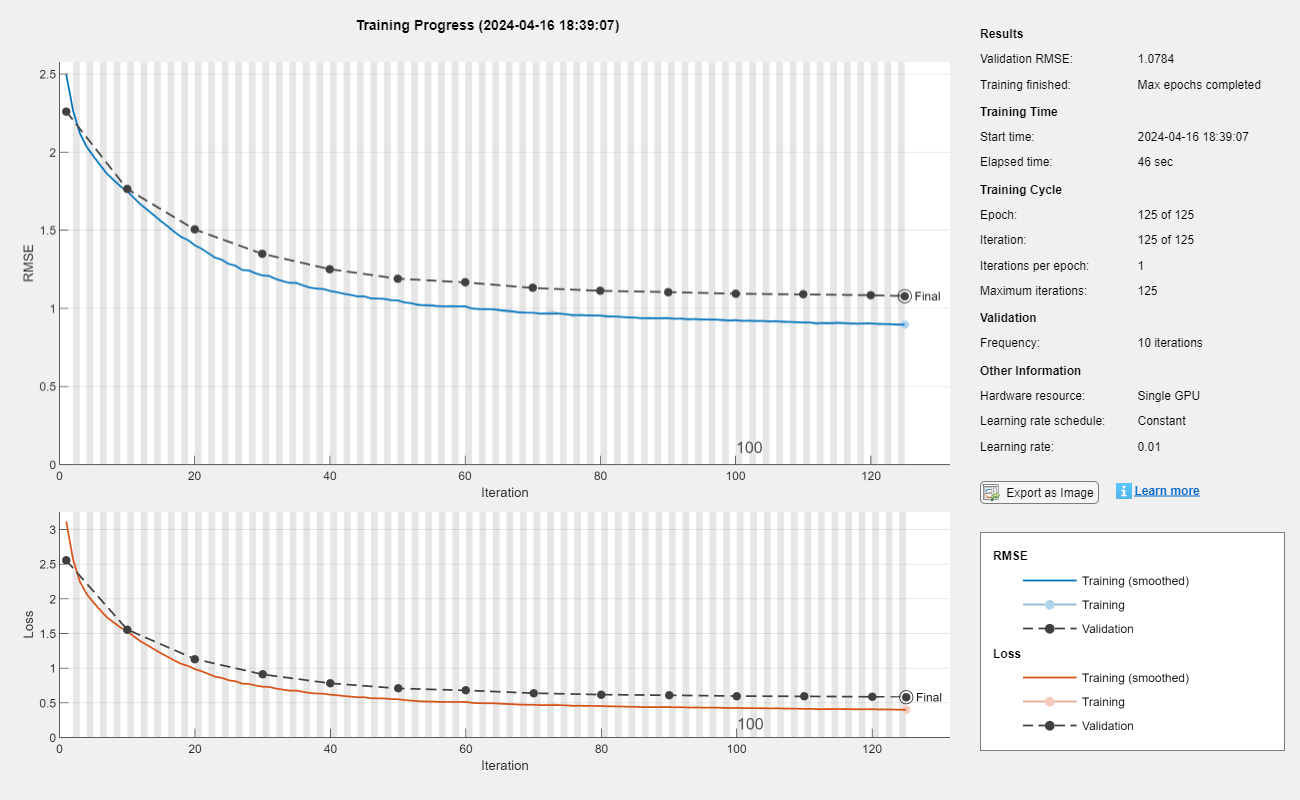

Hyperparameters: Hidden Units=12, Epochs=125, MiniBatchSize=128


Validation RMSE: 1.078352


-------------------------



% Create LSTM model

% layers = [
%     sequenceInputLayer(P, 'Name', 'input')
%     lstmLayer(numHiddenUnits, 'Name', 'lstm')
%     fullyConnectedLayer(F, 'Name', 'fc')
%     regressionLayer('Name', 'output')
% ];

% layers = [
%     sequenceInputLayer(P, 'Name', 'input')
%     lstmLayer(numHiddenUnits, 'Name', 'lstm1', 'OutputMode', 'sequence')
%     dropoutLayer(0.2, 'Name', 'dropout1')  % Optional: Dropout layer for regularization
%     lstmLayer(numHiddenUnits, 'Name', 'lstm2', 'OutputMode', 'sequence')
%     fullyConnectedLayer(64, 'Name', 'fc1')
%     reluLayer('Name', 'relu1')')
%     regressionLayer('Name', 'output')
% ];


% Define different values for hyperparameters
numHiddenUnitsList = 12;  % Add more values as needed, normally [12,24,32,48]
maxEpochsList = 125;  % Add more values as needed, normally [75,125,175]
miniBatchSizeList = 128;  % Add more values as needed, normally [32 64 128]

% Define variables to store the best hyperparameters and minimum validation RMSE
bestNumHiddenUnits = 0;
bestMaxEpochs = 0;
bestMiniBatchSize = 0;
minValidationRMSE = inf;

% Create a loop to iterate over hyperparameter values
for numHiddenUnits = numHiddenUnitsList
    for maxEpochs = maxEpochsList
        for miniBatchSize = miniBatchSizeList

            % Create or modify the layers and options based on the hyperparameters
            layers = [
                sequenceInputLayer(P, 'Name', 'input')
                lstmLayer(numHiddenUnits, 'Name', 'lstm', 'OutputMode', 'sequence')
                dropoutLayer(0.2, 'Name', 'dropout')  % Add a dropout layer
                fullyConnectedLayer(F, 'Name', 'fc')
                regressionLayer('Name', 'output')
            ];

            options = trainingOptions("adam", ...
                'MaxEpochs', maxEpochs, ...
                'MiniBatchSize', miniBatchSize, ...
                'SequencePaddingDirection', 'right', ...
                'SequenceLength', 'longest', ...
                'Shuffle', 'every-epoch', ...
                'InitialLearnRate', 0.01, ...
                'LearnRateDropFactor', 0.7, ...
                'LearnRateDropPeriod', 25, ...
                'Plots', 'training-progress', ...
                'Verbose', false, ...
                'ValidationData', {XValidation, YValidation}, ...
                'ValidationFrequency',10, ...
                'L2Regularization', 0.005);

                % 'GradientThreshold', 1, ...
                % 'InitialLearnRate', 0.01, ...
                % 'LearnRateDropFactor', 0.9, ...
                % 'LearnRateDropPeriod', 10, ...
                % 'LearnRateSchedule', 'piecewise', ..

                % 'InitialLearnRate', 0.01, ...
                % 'LearnRateDropFactor', 0.9, ...
                % 'LearnRateDropPeriod', 10, ...

            % Train the LSTM model
            [model, info] = trainNetwork(XTrain, YTrain, layers, options);

            % Extract the validation RMSE from the training progress
            validationRMSE = info.ValidationRMSE(end);

            % Compare with the minimum validation RMSE
            if validationRMSE < minValidationRMSE
                minValidationRMSE = validationRMSE;
                bestNumHiddenUnits = numHiddenUnits;
                bestMaxEpochs = maxEpochs;
                bestMiniBatchSize = miniBatchSize;
            end

            % Display or store results, such as RMSE, for each hyperparameter combination
            fprintf('Hyperparameters: Hidden Units=%d, Epochs=%d, MiniBatchSize=%d\n', numHiddenUnits, maxEpochs, miniBatchSize);
            fprintf('Validation RMSE: %f\n', validationRMSE);
            fprintf('-------------------------\n');
        end
    end
end



% Display the best hyperparameters and minimum validation RMSE
fprintf('Best Hyperparameters: Hidden Units=%d, Epochs=%d, MiniBatchSize=%d\n', bestNumHiddenUnits, bestMaxEpochs, bestMiniBatchSize);

Best Hyperparameters: Hidden Units=12, Epochs=125, MiniBatchSize=128


fprintf('Minimum Validation RMSE: %f\n', minValidationRMSE);

Minimum Validation RMSE: 1.078352


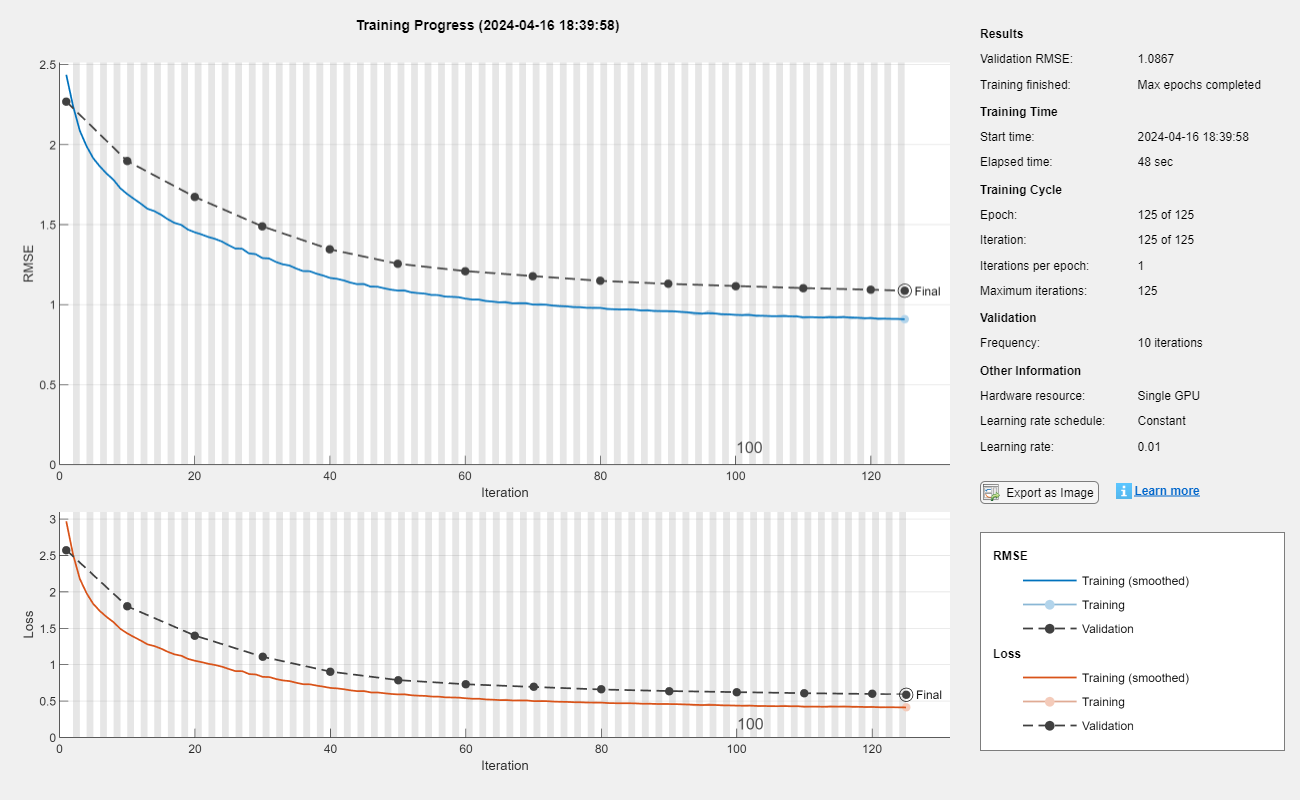


% Define the LSTM model architecture with the best hyperparameters
layers1 = [
    sequenceInputLayer(P, 'Name', 'input1')
    lstmLayer(bestNumHiddenUnits, 'Name', 'lstm1', 'OutputMode', 'sequence')
    dropoutLayer(0.2, 'Name', 'dropout1')  % Add a dropout layer
    fullyConnectedLayer(F, 'Name', 'fc1')
    regressionLayer('Name', 'output1')
    ];

options1 = trainingOptions("adam", ...
    'MaxEpochs', bestMaxEpochs, ...
    'MiniBatchSize', bestMiniBatchSize, ...
    'SequencePaddingDirection', 'right', ...
    'SequenceLength', 'longest', ...
    'Shuffle', 'every-epoch', ...
    'InitialLearnRate', 0.01, ...
    'LearnRateDropFactor', 0.7, ...
    'LearnRateDropPeriod', 25, ...
    'Plots', 'training-progress', ...
    'Verbose', false, ...
    'ValidationData', {XValidation, YValidation}, ...
    'ValidationFrequency',10, ...
    'L2Regularization', 0.005);


% Train the LSTM model
finalModel = trainNetwork(XTrain, YTrain, layers1, options1);


% Reset the model's state before making predictions
finalModel = resetState(finalModel);

% Add the testing and evaluation code here
SizeofXTest = size(XTest);
numXTest = SizeofXTest(2);
YPredicted_Test = zeros(F,numXTest); % Initialize the matrix to store predicted values zeros(F,numXTest)

for i = 1:numXTest
    % Extract the current input sequence
    currentSequence = XTest(:, i);

    % Reshape the input sequence to match the feature dimension of the model
    currentSequence = reshape(currentSequence, [P, 1, 1]);  % Reshape for LSTM input

    % Make a prediction for the next F time steps
    % Update YPredicted with the current prediction values
    currentPrediction = predict(finalModel, currentSequence, 'ExecutionEnvironment', 'cpu');  % Predict on GPU/CPU;

    % Update YPredicted with the current prediction values
    % Loop to fill each column of YPredicted
    for j = 1:F
        YPredicted_Test(j, i) = currentPrediction(j);
    end
end
% Display mean and standard deviation before destandardization
disp(['Before De-standardization: Mean(YTest): ' num2str(mean(YTest(:)))]);

Before De-standardization: Mean(YTest): 0.018061


disp(['Std(YTest): ' num2str(std(YTest(:)))]);

Std(YTest): 0.99619



% De-standardize the predictions and testing output using the same mu and sig
YPredicted_Test = sig_2 .* YPredicted_Test + mu_2;
YTest = sig_2 .* YTest + mu_2;

% Display mean and standard deviation after destandardization
disp(['After De-standardization: Mean(YTest): ' num2str(mean(YTest(:)))]);

After De-standardization: Mean(YTest): 2.541


disp(['Std(YTest): ' num2str(std(YTest(:)))]);

Std(YTest): 0.91503


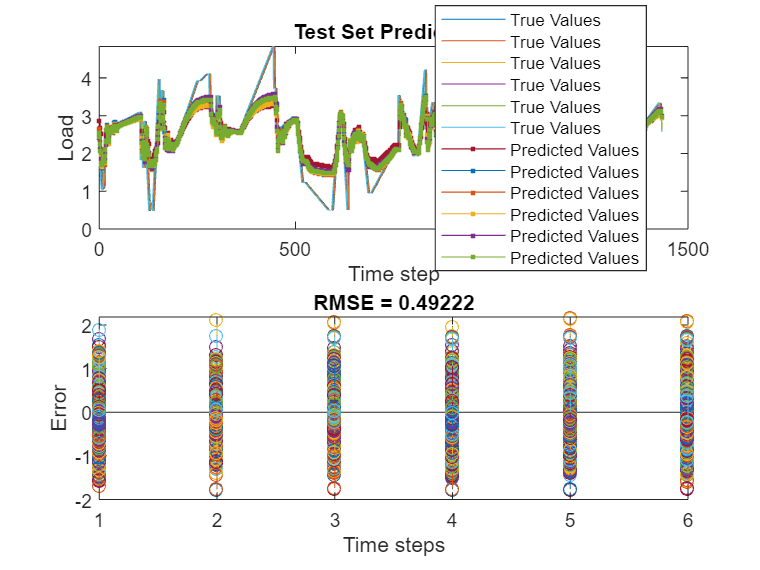


rmse = sqrt(mean((YPredicted_Test(:) - YTest(:)).^2));

% Visualize the results
figure;
subplot(2,1,1)
plot(1:length(YTest), YTest, '-','DisplayName', 'True Values');
hold on;
plot(1:length(YPredicted_Test), YPredicted_Test, '.-', 'DisplayName', 'Predicted Values');
xlabel("Time step");
ylabel("Load");
title("Test Set Predictions");
legend('Location', 'Best');
hold off;

subplot(2,1,2)
stem(YPredicted_Test - YTest)
xlabel("Time steps")
ylabel("Error")
title("RMSE = " + rmse)



YPredicted_Test_flatten = YPredicted_Test(1,:)

YPredicted_Test_flatten =     2.8657    2.8783    2.6891    2.5447    2.5318    2.1007    2.0191    1.7810    1.6253    1.7041    1.7011    1.6726    1.7840    1.7970    1.7156    1.9038    2.0332    2.2358    2.4649    2.5819    2.5727    2.6313    2.6198    2.6078    2.5911    2.5609    2.5391    2.6286    2.5628    2.6136    2.6300    2.5678    2.6880    2.5456    2.5847    2.5724    2.5512    2.6571    2.6696    2.7286    2.7277    2.7862    2.7124    2.7535    2.6932    2.6787    2.6634    2.7242    2.7173    2.7504


YTest_flatten = YTest(1,:)

YTest_flatten =     2.6094    2.4364    2.2634    2.0904    1.9174    1.7445    1.5715    1.3985    1.2255    1.0525    1.0525    1.0525    1.0947    1.0947    1.1370    1.9042    1.9042    2.6715    2.6715    2.6715    2.6715    2.6715    2.6715    2.6715    2.6715    2.6715    2.6768    2.6821    2.6874    2.6927    2.6981    2.7034    2.7087    2.7140    2.7193    2.7246    2.7299    2.7352    2.7405    2.7458    2.7512    2.7565    2.7618    2.7671    2.7724    2.7777    2.7830    2.7883    2.7936    2.7989


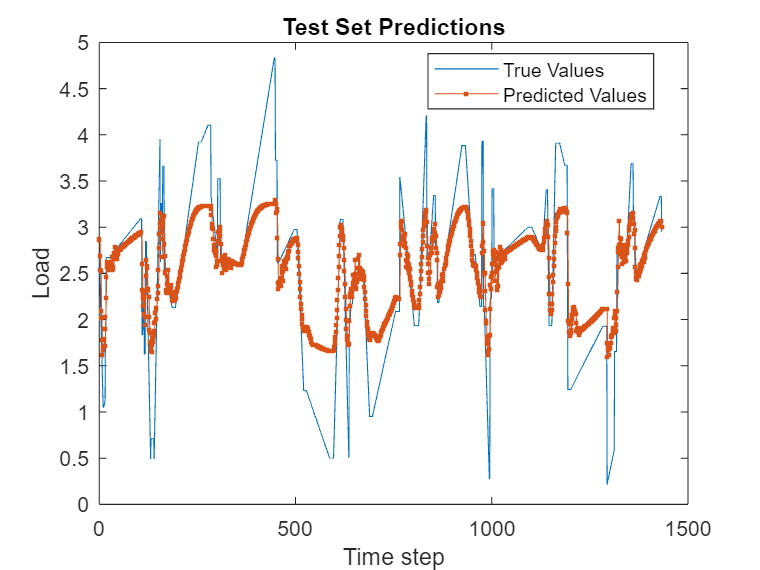


figure;
plot(1:length(YTest_flatten), YTest_flatten, '-','DisplayName', 'True Values');
hold on;
plot(1:length(YPredicted_Test_flatten), YPredicted_Test_flatten, '.-', 'DisplayName', 'Predicted Values');
xlabel("Time step");
ylabel("Load");
title("Test Set Predictions");
legend('Location', 'Best');
hold off;